syms m M l I t g u;
syms x dx ddx theta dtheta ddtheta;

%without tangent velocity of the load
Tvozik = 1/2*M*dx^2;
Vvozik = 0;
dvx = -l*cos(theta)*dtheta+dx;
dvy = l*sin(theta)*dtheta;
Tkyvadlo = 1/2*m*((dvx^2)+(dvy^2));
Vkyvadlo = -m*g*l*cos(theta);
T = Tvozik +Tkyvadlo 

$$T = \frac{M\,{\mathrm{dx}}^{2}}{2}+\frac{m\,\left({\left(\mathrm{dx}-\mathrm{dtheta}\,l\,\cos\left(\theta \right)\right)}^{2}+{\mathrm{dtheta}}^{2}\,l^{2}\,{\sin\left(\theta \right)}^{2}\right)}{2}$$

V = Vvozik + Vkyvadlo

$$V = -g\,l\,m\,\cos\left(\theta \right)$$


%with tangent velocity of the load
%T = 1/2*M*dx^2+1/2*m*(dtheta*l*cos(theta)+dx)^2
%V = -m*g*l*cos(theta)

% T=  1/2*M*dxdt^2+1/2*m*(dthetadt^2*l^2+2*cos(theta)*dthetadt*dxdt*l+dxdt^2)
% V = -m*g*l*cos(theta)
L = T - V

$$L = \frac{M\,{\mathrm{dx}}^{2}}{2}+\frac{m\,\left({\left(\mathrm{dx}-\mathrm{dtheta}\,l\,\cos\left(\theta \right)\right)}^{2}+{\mathrm{dtheta}}^{2}\,l^{2}\,{\sin\left(\theta \right)}^{2}\right)}{2}+g\,l\,m\,\cos\left(\theta \right)$$

% D1 = diff(L,diff(x(t),t));
% D2 = diff(L,x);
% L1 = diff(D1,t) - D2 == F1;
% L1 = simplify(L1)
% 
% D3 = diff(L,diff(theta(t),t))
% D4 = diff(L,theta)
% L2 = diff(D3,t) - D4 == F2;
% L2 = simplify(L2)


q = [x; theta]; %generalized coordinates
dq = [dx; dtheta];
ddq = [ddx; ddtheta];
F = [u;0];

dLddq = jacobian(L,dq)

$$dLddq = \left(\begin{array}{cc} M\,\mathrm{dx}+\frac{m\,\left(2\,\mathrm{dx}-2\,\mathrm{dtheta}\,l\,\cos\left(\theta \right)\right)}{2} & -\frac{m\,\left(2\,l\,\cos\left(\theta \right)\,\left(\mathrm{dx}-\mathrm{dtheta}\,l\,\cos\left(\theta \right)\right)-2\,\mathrm{dtheta}\,l^{2}\,{\sin\left(\theta \right)}^{2}\right)}{2} \end{array}\right)$$

dLdq = jacobian(L,q)

$$dLdq = \left(\begin{array}{cc} 0 & \frac{m\,\left(2\,{\mathrm{dtheta}}^{2}\,l^{2}\,\cos\left(\theta \right)\,\sin\left(\theta \right)+2\,\mathrm{dtheta}\,l\,\sin\left(\theta \right)\,\left(\mathrm{dx}-\mathrm{dtheta}\,l\,\cos\left(\theta \right)\right)\right)}{2}-g\,l\,m\,\sin\left(\theta \right) \end{array}\right)$$

%chain rule of derivation with respect to time
ddtdLddq = jacobian(dLddq,dq)*ddq + jacobian(dLddq,q)*dq

$$ddtdLddq = \left(\begin{array}{c} l\,m\,\sin\left(\theta \right)\,{\mathrm{dtheta}}^{2}+\mathrm{ddx}\,\left(M+m\right)-\mathrm{ddtheta}\,l\,m\,\cos\left(\theta \right)\\ \frac{\mathrm{dtheta}\,m\,\left(2\,l\,\sin\left(\theta \right)\,\left(\mathrm{dx}-\mathrm{dtheta}\,l\,\cos\left(\theta \right)\right)+2\,\mathrm{dtheta}\,l^{2}\,\cos\left(\theta \right)\,\sin\left(\theta \right)\right)}{2}+\frac{\mathrm{ddtheta}\,m\,\left(2\,l^{2}\,{\cos\left(\theta \right)}^{2}+2\,l^{2}\,{\sin\left(\theta \right)}^{2}\right)}{2}-\mathrm{ddx}\,l\,m\,\cos\left(\theta \right) \end{array}\right)$$


%Equations of Motion
EOM = ddtdLddq - transpose(dLdq) - F;
adadsd = simplify(EOM)

$$adadsd = \left(\begin{array}{c} l\,m\,\sin\left(\theta \right)\,{\mathrm{dtheta}}^{2}-u+\mathrm{ddx}\,\left(M+m\right)-\mathrm{ddtheta}\,l\,m\,\cos\left(\theta \right)\\ l\,m\,\left(\mathrm{ddtheta}\,l-\mathrm{ddx}\,\cos\left(\theta \right)+g\,\sin\left(\theta \right)\right) \end{array}\right)$$

solution = solve(EOM,ddq)

solution = struct with fields:
        ddx: -(dtheta^2*l*m*sin(theta)^3 - u*sin(theta)^2 - u*cos(theta)^2 + g*m*cos(theta)*sin(theta) + dtheta^2*l*m*cos(theta)^2*sin(theta))/(m*sin(theta)^2 + M*cos(theta)^2 + M*sin(theta)^2)
    ddtheta: -(l*m*cos(theta)*sin(theta)*dtheta^2 - u*cos(theta) + g*m*sin(theta) + M*g*sin(theta))/(M*l*cos(theta)^2 + M*l*sin(theta)^2 + l*m*sin(theta)^2)



ddxSolution = simplify(solution.ddx)

$$ddxSolution = -\frac{l\,m\,\sin\left(\theta \right)\,{\mathrm{dtheta}}^{2}-u+g\,m\,\cos\left(\theta \right)\,\sin\left(\theta \right)}{-m\,{\cos\left(\theta \right)}^{2}+M+m}$$

ddthetaSolution = simplify(solution.ddtheta)

$$ddthetaSolution = -\frac{l\,m\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,{\mathrm{dtheta}}^{2}-u\,\cos\left(\theta \right)+g\,m\,\sin\left(\theta \right)+M\,g\,\sin\left(\theta \right)}{l\,\left(-m\,{\cos\left(\theta \right)}^{2}+M+m\right)}$$

syms x1 x2 x3 x4 t u g m l M
g = 9.81;
l=0.35;
m = 0.25;
M = 2;
f1 = x2

$$f1 = x_{2}$$

f2 = (-l*m*sin(x3)*x4^2+u-m*g*cos(x3)*sin(x3))/(-m*cos(x3)^2+M+m)

$$f2 = \frac{\frac{7\,\sin\left(x_{3}\right)\,{x_{4}}^{2}}{80}-u+\frac{981\,\cos\left(x_{3}\right)\,\sin\left(x_{3}\right)}{400}}{\frac{{\cos\left(x_{3}\right)}^{2}}{4}-\frac{9}{4}}$$

f3 = x4

$$f3 = x_{4}$$

f4 = (-l*m*cos(x3)*sin(x3)*x4^2+u*cos(x3)-g*m*sin(x3)-M*g*sin(x3))/(l*(-m*cos(x3)^2+M+m))

$$f4 = \frac{\frac{7\,\cos\left(x_{3}\right)\,\sin\left(x_{3}\right)\,{x_{4}}^{2}}{80}+\frac{8829\,\sin\left(x_{3}\right)}{400}-u\,\cos\left(x_{3}\right)}{\frac{7\,{\cos\left(x_{3}\right)}^{2}}{80}-\frac{63}{80}}$$


%version with tangent velocity of load
%f2 = (u * cos(x3) + g * m * sin(x3)) / (M * cos(x3));
%f3= (-(-M*l*cos(x3)*sin(x3)*x4^2 + u*cos(x3) + g*m*sin(x3) + M*g*sin(x3))) / (M*l*cos(x3)^2);

% Calculate the Jacobians
J_A = jacobian([f1,f2,f3,f4],[x1, x2, x3, x4])

$$J\_A = \begin{array}{l} \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & \frac{\frac{7\,{x_{4}}^{2}\,\cos\left(x_{3}\right)}{80}+\frac{981\,{\cos\left(x_{3}\right)}^{2}}{400}-\frac{981\,{\sin\left(x_{3}\right)}^{2}}{400}}{\sigma_{2}}+\frac{\cos\left(x_{3}\right)\,\sin\left(x_{3}\right)\,\left(\frac{7\,\sin\left(x_{3}\right)\,{x_{4}}^{2}}{80}-u+\frac{981\,\cos\left(x_{3}\right)\,\sin\left(x_{3}\right)}{400}\right)}{2\,{\sigma_{2}}^{2}} & \frac{7\,x_{4}\,\sin\left(x_{3}\right)}{40\,\sigma_{2}}\\ 0 & 0 & 0 & 1\\ 0 & 0 & \frac{\frac{7\,{x_{4}}^{2}\,{\cos\left(x_{3}\right)}^{2}}{80}-\frac{7\,{x_{4}}^{2}\,{\sin\left(x_{3}\right)}^{2}}{80}+\frac{8829\,\cos\left(x_{3}\right)}{400}+u\,\sin\left(x_{3}\right)}{\sigma_{1}}+\frac{7\,\cos\left(x_{3}\right)\,\sin\left(x_{3}\right)\,\left(\frac{7\,\cos\left(x_{3}\right)\,\sin\left(x_{3}\right)\,{x_{4}}^{2}}{80}+\frac{8829\,\sin\left(x_{3}\right)}{400}-u\,\cos\left(x_{3}\right)\right)}{40\,{\sigma_{1}}^{2}} & \frac{7\,x_{4}\,\cos\left(x_{3}\right)\,\sin\left(x_{3}\right)}{40\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{7\,{\cos\left(x_{3}\right)}^{2}}{80}-\frac{63}{80}\\ \sigma_{2}=\frac{{\cos\left(x_{3}\right)}^{2}}{4}-\frac{9}{4} \end{array}$$

J_B = jacobian([f1,f2,f3,f4],[u])

$$J\_B = \left(\begin{array}{c} 0\\ -\frac{1}{\frac{{\cos\left(x_{3}\right)}^{2}}{4}-\frac{9}{4}}\\ 0\\ -\frac{\cos\left(x_{3}\right)}{\frac{7\,{\cos\left(x_{3}\right)}^{2}}{80}-\frac{63}{80}} \end{array}\right)$$


% Substitute all symbolic variables
subs_J_A = subs(J_A, [x1, x2, x3, x4, u, g, l, m, M], [0, 0, 0, 0, 0, g, l, m, M])

$$subs\_J\_A = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & -\frac{981}{800} & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & -\frac{8829}{280} & 0 \end{array}\right)$$

subs_J_B = subs(J_B, [x1, x2, x3, x4, u, g, l, m, M], [0, 0, 0, 0, 0, g, l, m, M])

$$subs\_J\_B = \left(\begin{array}{c} 0\\ \frac{1}{2}\\ 0\\ \frac{10}{7} \end{array}\right)$$


% Convert to double
A = double(subs_J_A)

A =          0    1.0000         0         0
         0         0   -1.2263         0
         0         0         0    1.0000
         0         0  -31.5321         0


B = double(subs_J_B)

B =          0
    0.5000
         0
    1.4286



C = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]

C =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


D=[0;0;0;0]

D =      0
     0
     0
     0



% Check controllability
rank(ctrb(A,B))

ans = 4

ctrb(A,B)

ans =          0    0.5000         0   -1.7518
    0.5000         0   -1.7518         0
         0    1.4286         0  -45.0459
    1.4286         0  -45.0459         0


% Your continuous-time state-space system
sys = ss(A, B, C, D);

Ts = 0.033; %  milliseconds

sys_d = c2d(sys, Ts, ['zoh'])

sys_d =
 
  A = 
               x1          x2          x3          x4
   x1           1       0.033  -0.0006658  -7.332e-06
   x2           0           1    -0.04024  -0.0006658
   x3           0           0      0.9829     0.03281
   x4           0           0      -1.035      0.9829
 
  B = 
              u1
   x1  0.0002722
   x2    0.01649
   x3  0.0007756
   x4    0.04687
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Sample time: 0.033 seconds
Discrete-time state-space model.



A_d = sys_d.A

A_d =     1.0000    0.0330   -0.0007   -0.0000
         0    1.0000   -0.0402   -0.0007
         0         0    0.9829    0.0328
         0         0   -1.0346    0.9829


B_d = sys_d.B

B_d =     0.0003
    0.0165
    0.0008
    0.0469


%plot

figure;
plot(out.linearTheta.Time,out.linearTheta.Data);

Unable to resolve the name 'out.linearTheta.Time'.

grid on;
hold on;
plot(out.nonLinearTheta.Time,out.nonLinearTheta.Data);
legend("linearizovaný model", "nelineární model")
title("Validace modelu")
xlabel("čas [s]")
ylabel("\theta [rad]")

figure;
plot(out.linearTheta.Time,out.linearTheta.Data);
grid on;
hold on;
plot(out.nonLinearTheta.Time,out.nonLinearTheta.Data);
legend("linearizovaný model", "nelineární model")
title("Validace řízení")
xlabel("čas [s]")
ylabel("\theta' [rad \cdot s^{-1}]")

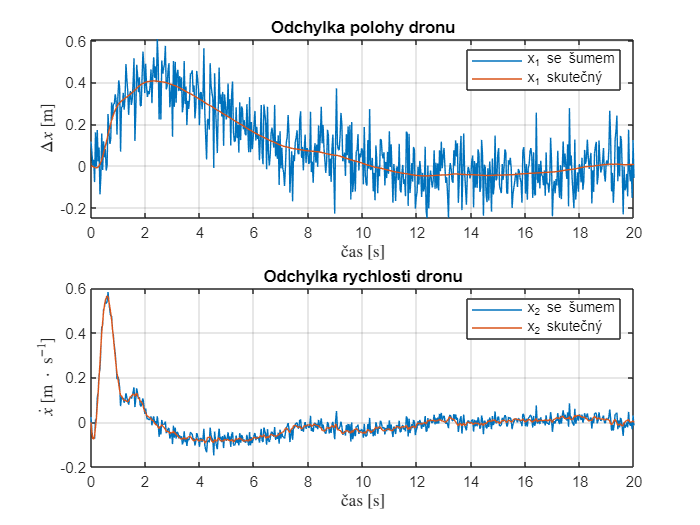

%plot

x1_noise = out.simout.Data(:,1);
x1_clean = out.no_noise.Data(:,1);
x2_noise = out.simout.Data(:,2);
x2_clean = out.no_noise.Data(:,2);
x3_noise = out.simout.Data(:,3);
x3_clean = out.no_noise.Data(:,3);
x4_noise = out.simout.Data(:,4);
x4_clean = out.no_noise.Data(:,4);
% První figura s x1 a x2
figure;

% Graf pro x1
subplot(2,1,1);
plot(out.simout.Time, x1_noise);
hold on;
plot(out.no_noise.Time,x1_clean);
grid on;
legend("x_1 se šumem", "x_1 skutečný");
title("Odchylka polohy dronu"); % Removed 'Interpreter', 'latex'
xlabel("\v{c}as [s]", 'Interpreter', 'latex'); % Updated to include \v{c} for "č"
ylabel("$\Delta x$ [m]", 'Interpreter', 'latex');
hold off;

% Graf pro x2
subplot(2,1,2);
plot(out.simout.Time, x2_noise);
hold on;
plot(out.no_noise.Time,x2_clean);
grid on;
legend("x_2 se šumem", "x_2 skutečný");
title("Odchylka rychlosti dronu"); % Removed 'Interpreter', 'latex'
xlabel("\v{c}as [s]", 'Interpreter', 'latex');
ylabel("$\dot{x}$ [m $\cdot$ s$^{-1}$]", 'Interpreter', 'latex');
hold off;

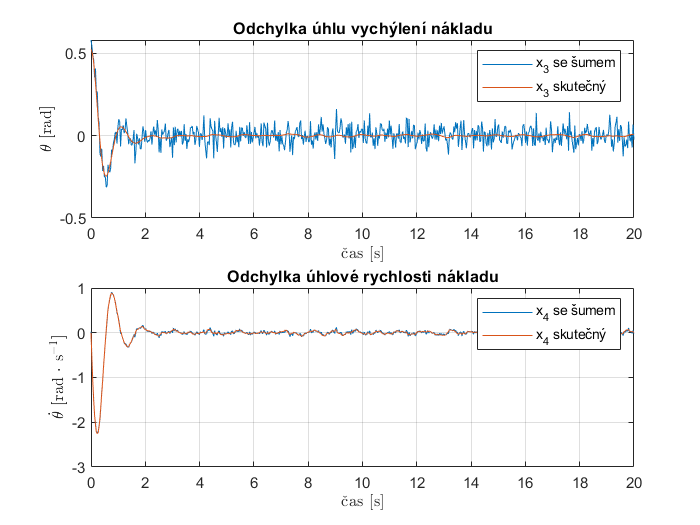


% Druhá figura s x3 a x4
figure;

% Graf pro x3
subplot(2,1,1);
plot(out.simout.Time, x3_noise);
hold on;
plot(out.no_noise.Time,x3_clean);
grid on;
legend("x_3 se šumem", "x_3 skutečný");
title("Odchylka úhlu vychýlení nákladu"); % Removed 'Interpreter', 'latex'
xlabel("\v{c}as [s]", 'Interpreter', 'latex');
ylabel("$\theta$ [rad]", 'Interpreter', 'latex');
hold off;

% Graf pro x4
subplot(2,1,2);
plot(out.simout.Time, x4_noise);
hold on;
plot(out.no_noise.Time,x4_clean);
grid on;
legend("x_4 se šumem", "x_4 skutečný");
title("Odchylka úhlové rychlosti nákladu"); % Removed 'Interpreter', 'latex'
xlabel("\v{c}as [s]", 'Interpreter', 'latex');
ylabel("$\dot{\theta}$ [rad $\cdot$ s$^{-1}$]", 'Interpreter', 'latex');
hold off;

% Graf pro x1
subplot(2,1,1);
plot(out.simout.Time, out.simout.Data(:, 1)); % Assuming x1 is the first column in simout.Data
grid on;
legend("x_1");
title("Odchylka polohy dronu");
xlabel("\v{c}as [s]", 'Interpreter', 'latex');
ylabel("$\Delta x$ [m]", 'Interpreter', 'latex');
hold off;

% Graf pro x2
subplot(2,1,2);
plot(out.simout.Time, out.simout.Data(:, 2)); % Assuming x2 is the second column in simout.Data
grid on;
legend("x_2");
title("Odchylka rychlosti dronu");
xlabel("\v{c}as [s]", 'Interpreter', 'latex');
ylabel("$\dot{x}$ [m $\cdot$ s$^{-1}$]", 'Interpreter', 'latex');
hold off;

% Since we're plotting only simout data, the figure setup for x3 and x4 is similar:
figure;

% Graf pro x3
subplot(2,1,1);
plot(out.simout.Time, out.simout.Data(:, 3)); % Assuming x3 is the third column in simout.Data
grid on;
legend("x_3");
title("Odchylka úhlu vychýlení nákladu");
xlabel("\v{c}as [s]", 'Interpreter', 'latex');
ylabel("$\theta$ [rad]", 'Interpreter', 'latex');
hold off;

% Graf pro x4
subplot(2,1,2);
plot(out.simout.Time, out.simout.Data(:, 4)); % Assuming x4 is the fourth column in simout.Data
grid on;
legend("x_4");
title("Odchylka úhlové rychlosti nákladu");
xlabel("\v{c}as [s]", 'Interpreter', 'latex');
ylabel("$\dot{\theta}$ [rad $\cdot$ s$^{-1}$]", 'Interpreter', 'latex');
hold off;


if rank(ctrb(A_d,B_d))==4
    disp('System is controllable');
else
    disp('System is not controllable');
end

System is controllable


x1max = 4;  
x2max = 2.0;
x3max = pi/16;
x4max = 1.5;
u1max = 2.3;
%LQR Controller
Q = [1/(x1max)^2 0 0 0; 0 1/(x2max)^2 0 0; 0 0 1/(x3max)^2 0; 0 0 0 1/(x4max)^2] %cost on states

Q =     0.0625         0         0         0
         0    0.2500         0         0
         0         0   25.9382         0
         0         0         0    0.4444


R = 1/(u1max)^2 %cost on inputs

R = 0.1890

[K,S,E] = lqr(A,B,Q,R)

K =     0.5750    2.1165    4.8574    2.3569


S =     0.2301    0.2984    0.2562   -0.0283
    0.2984    1.0722    0.9713   -0.0952
    0.2562    0.9713   12.9320    0.3028
   -0.0283   -0.0952    0.3028    0.3452


E =   -0.4050 + 0.2495i
  -0.4050 - 0.2495i
  -1.8075 + 5.6865i
  -1.8075 - 5.6865i



% Now you can apply LQR on the discretized system
[K_d, S_d, E_d] = dlqr(A_d, B_d, Q, R)

K_d =     0.5346    1.9766    3.2881    2.2572


S_d =     7.0030    9.0436    7.7811   -0.8565
    9.0436   32.6220   29.4987   -2.8760
    7.7811   29.4987  405.6268    9.2111
   -0.8565   -2.8760    9.2111   10.7065


E_d =    0.9867 + 0.0081i
   0.9867 - 0.0081i
   0.9256 + 0.1758i
   0.9256 - 0.1758i


% K_d = 

% Check the properties of the discretized system
eig(A_d - B_d * K_d)

ans =    0.9256 + 0.1758i
   0.9256 - 0.1758i
   0.9867 + 0.0081i
   0.9867 - 0.0081i
